load("lidarSensorParameters.mat")
warning ("off","all");
open_system("testLidarSensorPlacement.slx");
warning ("off","all");

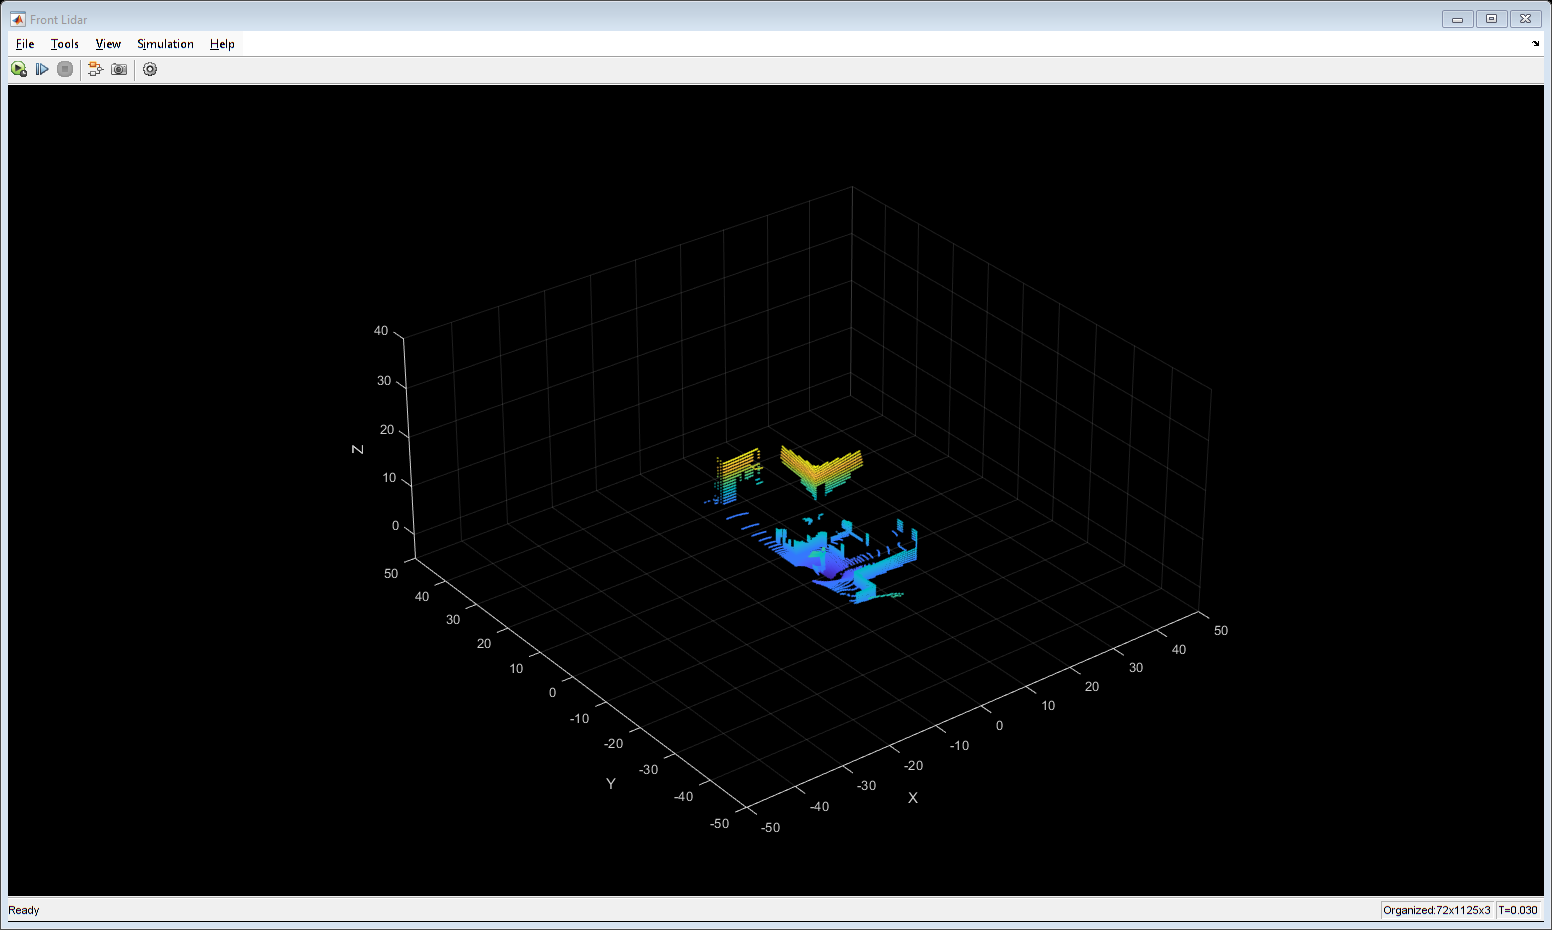

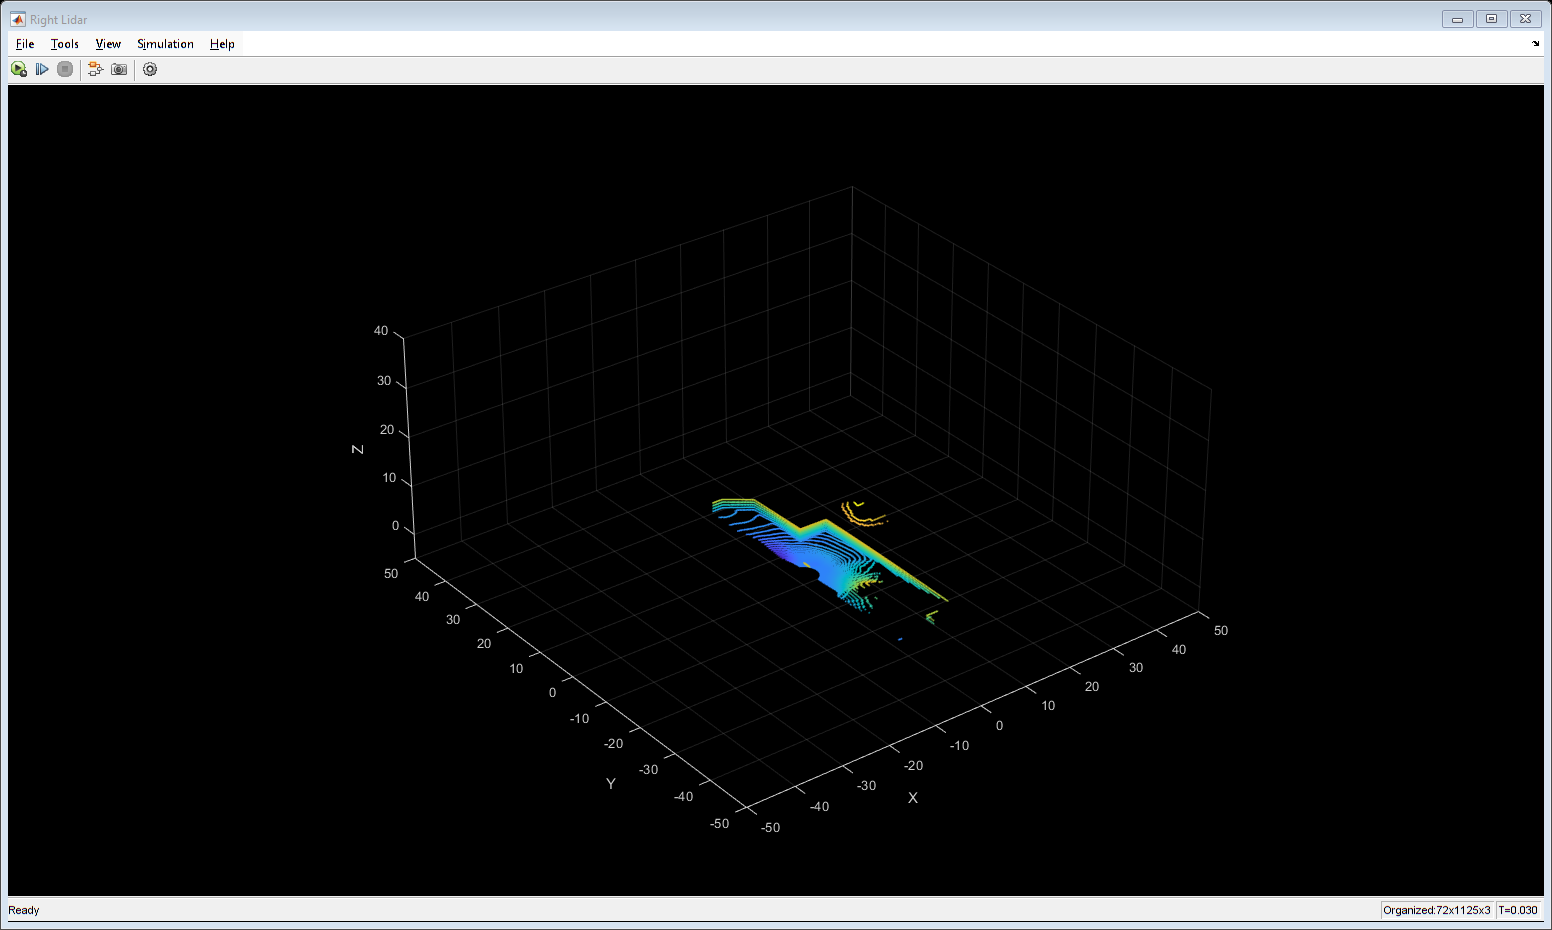

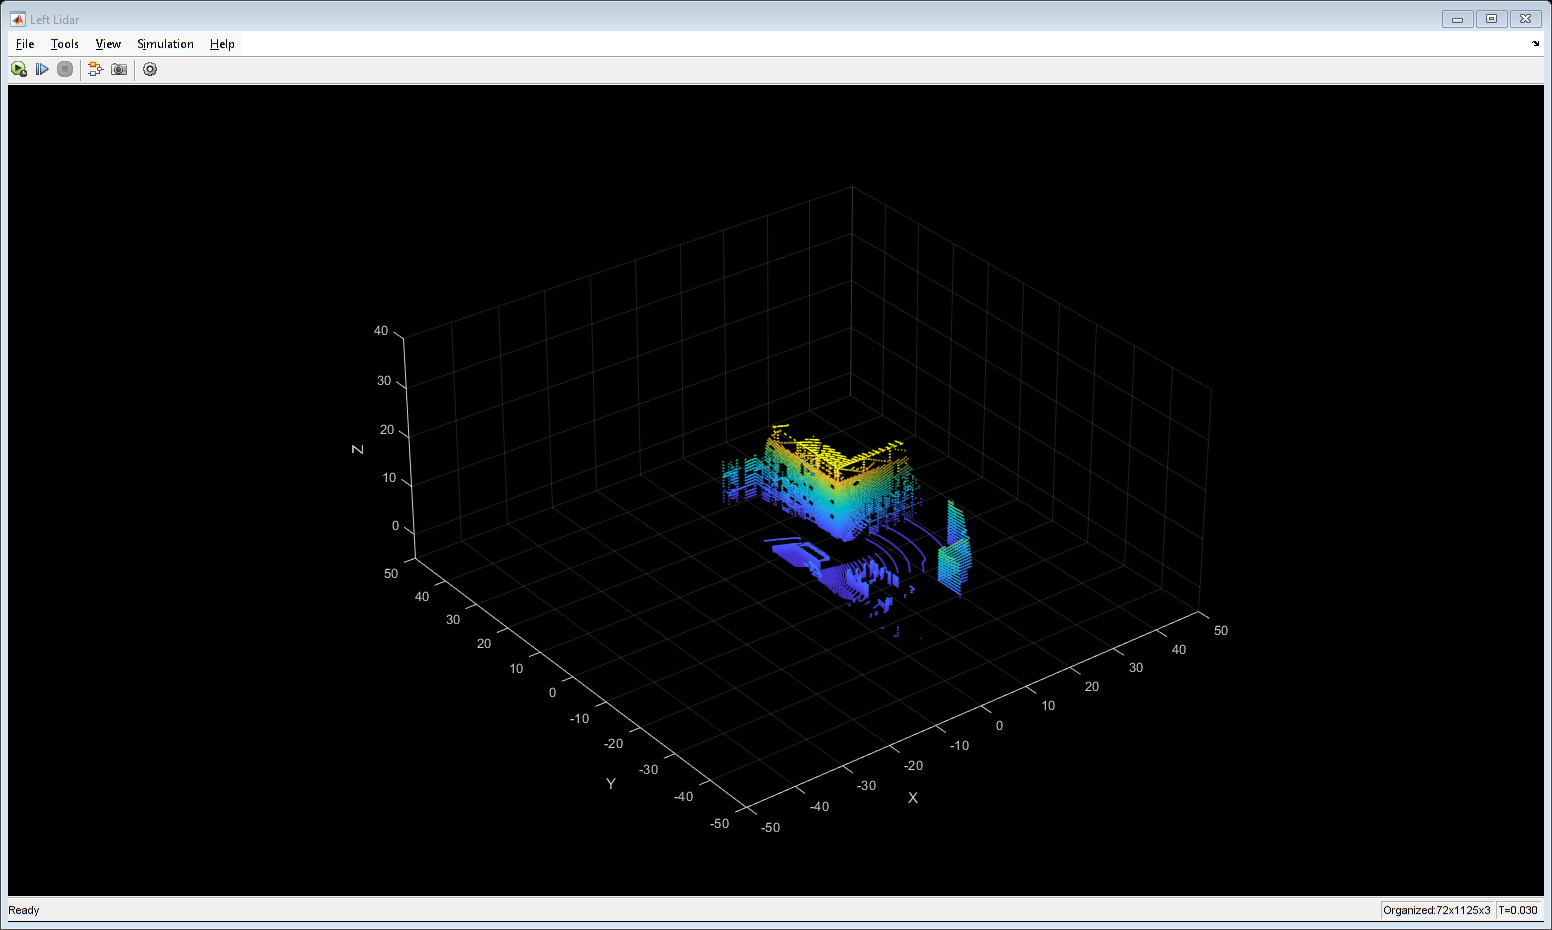

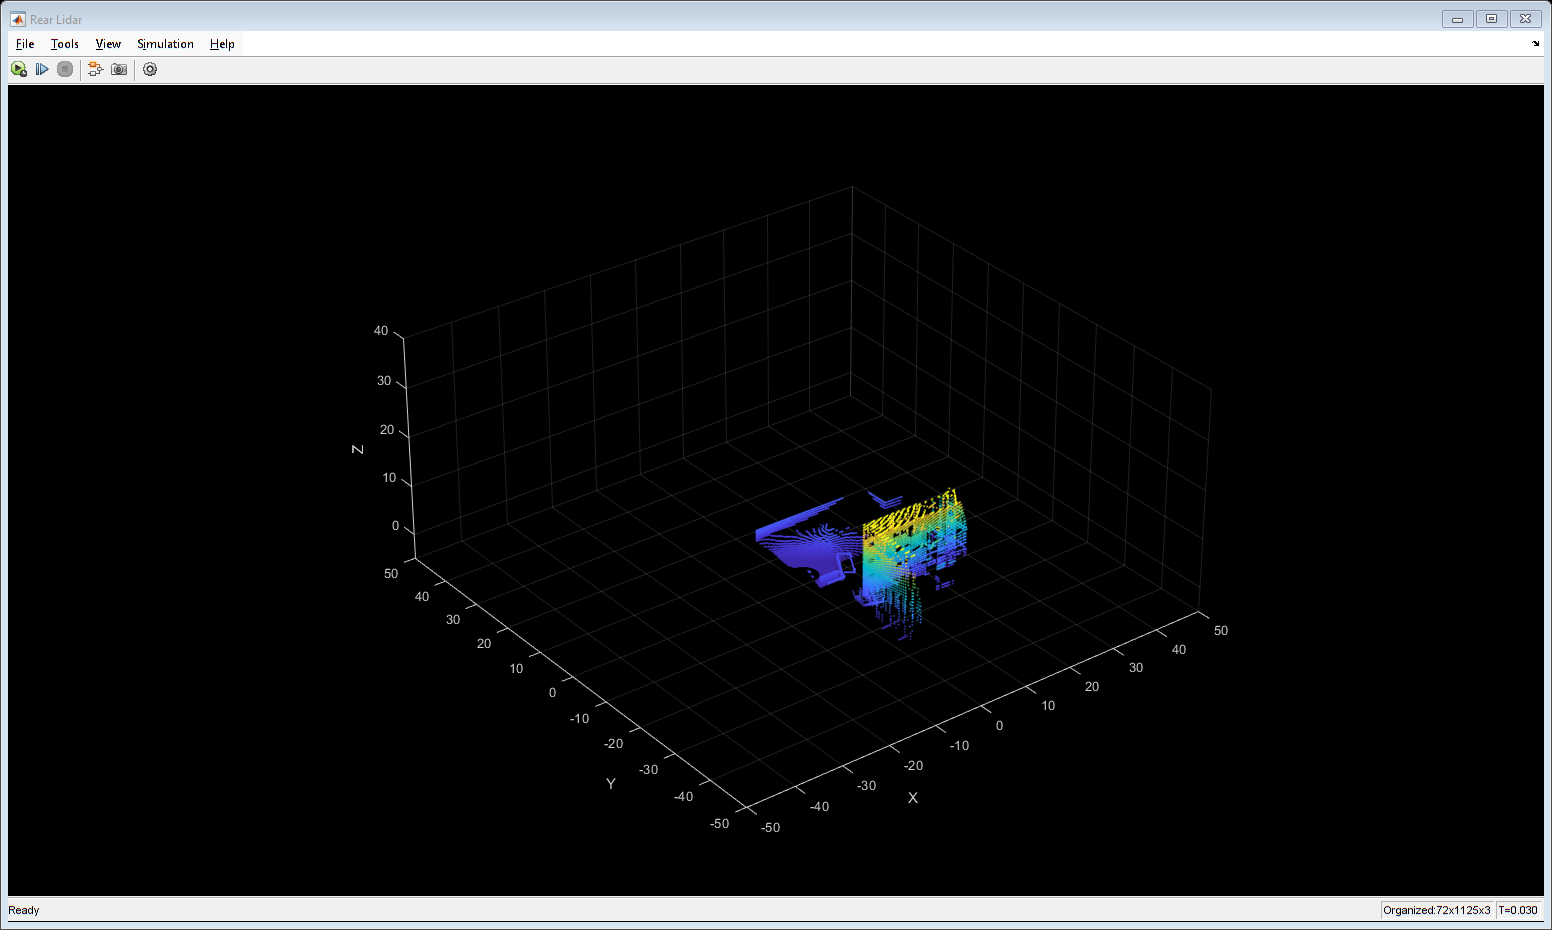

out = sim("testLidarSensorPlacement.slx", "StopTime", "0.03");


lidarData = out.logsout{1}.Values;

exampleLidarPointClouds = struct;

exampleLidarPointClouds.Front_Lidar.Point_Cloud = out.logsout{1}.Values.Front_Lidar.Point_Cloud.Data;
exampleLidarPointClouds.Front_Lidar.Translation = out.logsout{1}.Values.Front_Lidar.Translation.Data;
exampleLidarPointClouds.Front_Lidar.Rotation    = out.logsout{1}.Values.Front_Lidar.Rotation.Data;

exampleLidarPointClouds.Rear_Lidar.Point_Cloud = out.logsout{1}.Values.Rear_Lidar.Point_Cloud.Data;
exampleLidarPointClouds.Rear_Lidar.Translation = out.logsout{1}.Values.Rear_Lidar.Translation.Data;
exampleLidarPointClouds.Rear_Lidar.Rotation    = out.logsout{1}.Values.Rear_Lidar.Rotation.Data;

exampleLidarPointClouds.Left_Lidar.Point_Cloud = out.logsout{1}.Values.Left_Lidar.Point_Cloud.Data;
exampleLidarPointClouds.Left_Lidar.Translation = out.logsout{1}.Values.Left_Lidar.Translation.Data;
exampleLidarPointClouds.Left_Lidar.Rotation    = out.logsout{1}.Values.Left_Lidar.Rotation.Data;

exampleLidarPointClouds.Right_Lidar.Point_Cloud = out.logsout{1}.Values.Right_Lidar.Point_Cloud.Data;
exampleLidarPointClouds.Right_Lidar.Translation = out.logsout{1}.Values.Right_Lidar.Translation.Data;
exampleLidarPointClouds.Right_Lidar.Rotation    = out.logsout{1}.Values.Right_Lidar.Rotation.Data;

prj = currentProject;
savePath = fullfile(prj.RootFolder, "SensorModeling", "Lidar", "exampleLidarPointClouds");
save(savePath, "exampleLidarPointClouds");